%% plot_shelf_forcing_nc.m
% Load a CMEMS GLORYS12 NetCDF extract and plot temperature & salinity
% as functions of time (x, labelled by month) and depth (y).
%
% Author: Claude (for user), 2026

clear; close all; clc;

%% --- 1. Point to the file and inspect its contents ---
fname = "C:\Users\efc4\OneDrive - University of St Andrews\Desktop\PhD\umq_fjords\data\GLORYS12\loc2_cmems_mod_glo_phy_my_0.083deg_P1D-m_1778684403164.nc";

info = ncinfo(fname);
disp('--- Variables in the NetCDF file ---')

--- Variables in the NetCDF file ---


for k = 1:numel(info.Variables)
    v = info.Variables(k);
    dimStr = strjoin({v.Dimensions.Name}, ' x ');
    fprintf('  %-15s [%s]\n', v.Name, dimStr);
end

  time            [time]
  depth           [depth]
  latitude        [latitude]
  longitude       [longitude]
  thetao          [longitude x latitude x depth x time]
  so              [longitude x latitude x depth x time]



%% --- 2. Read coordinate variables ---
% Standard CMEMS global reanalysis (GLORYS12) names:
%   longitude, latitude, depth, time, thetao (temperature), so (salinity)
% Edit these if ncinfo above shows different names.

lon   = ncread(fname, 'longitude');
lat   = ncread(fname, 'latitude');
z     = ncread(fname, 'depth');
tRaw  = ncread(fname, 'time');

% Time units/calendar (e.g. "hours since 1950-01-01 00:00:00")
timeVarInfo = ncinfo(fname, 'time');
unitsAtt = timeVarInfo.Attributes(strcmp({timeVarInfo.Attributes.Name}, 'units'));
timeUnits = unitsAtt.Value;
fprintf('\nTime units string: %s\n', timeUnits);


Time units string: seconds since 1970-01-01 00:00:00



% Parse "<unit> since <reference date>"
parts = split(timeUnits, 'since');
unit = strtrim(parts{1});
refDate = datetime(strtrim(parts{2}), 'InputFormat', 'yyyy-MM-dd HH:mm:ss');

switch lower(unit)
    case 'seconds'
        tDate = refDate + seconds(tRaw);
    case 'hours'
        tDate = refDate + hours(tRaw);
    case 'days'
        tDate = refDate + days(tRaw);
    otherwise
        error('Unrecognised time unit "%s" - edit the switch statement above.', unit);
end

%% --- 3. Read temperature and salinity ---
% thetao/so dimensions are typically [lon x lat x depth x time].
% If this is a single-point extraction, lon/lat may have length 1.
thetao = ncread(fname, 'thetao'); % temperature, degC
so     = ncread(fname, 'so');     % salinity, PSU

fprintf('\nSize of thetao: %s\n', mat2str(size(thetao)));


Size of thetao: [1 1 41 12171]


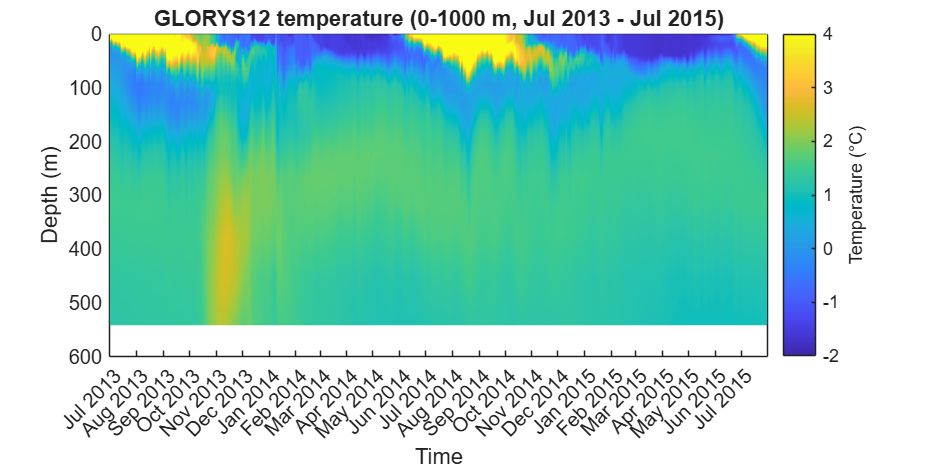


% Squeeze out singleton lon/lat dimensions (single-point extraction),
% leaving a depth x time matrix.
T   = squeeze(thetao);
Sal = squeeze(so);

% After squeezing, confirm orientation is depth (rows) x time (columns)
if isequal(size(T), [numel(tDate), numel(z)])
    T   = T.';
    Sal = Sal.';
end

%% --- 4. Restrict to 0-1000 m depth and Jul 2013 - Jul 2015 ---
depthLims = [0 600];
timeLims  = [datetime(2013,7,1) datetime(2015,7,31)];

zMask = z >= depthLims(1) & z <= depthLims(2);
tMask = tDate >= timeLims(1) & tDate <= timeLims(2);

zSub     = z(zMask);
tDateSub = tDate(tMask);
Tsub     = T(zMask, tMask);
Salsub   = Sal(zMask, tMask);

%% --- 5. Plot temperature ---
figure('Color','w','Position',[100 100 900 450]);
pcolor(tDateSub, zSub, Tsub); shading interp;
set(gca,'YDir','reverse'); % depth increases downward
ylim(depthLims);
try
    colormap(gca, cmocean('thermal')); % requires cmocean toolbox
catch
    colormap(gca, 'parula');
end
cb = colorbar; ylabel(cb, 'Temperature (\circC)');
clim([-2 4]); % fixed colour axis range
xlabel('Time'); ylabel('Depth (m)');
title('GLORYS12 temperature (0-1000 m, Jul 2013 - Jul 2015)');
ax = gca;
ax.XAxis.TickLabelFormat = 'MMM yyyy';
ax.XTick = dateshift(min(tDateSub),'start','month'):calmonths(1):dateshift(max(tDateSub),'start','month');

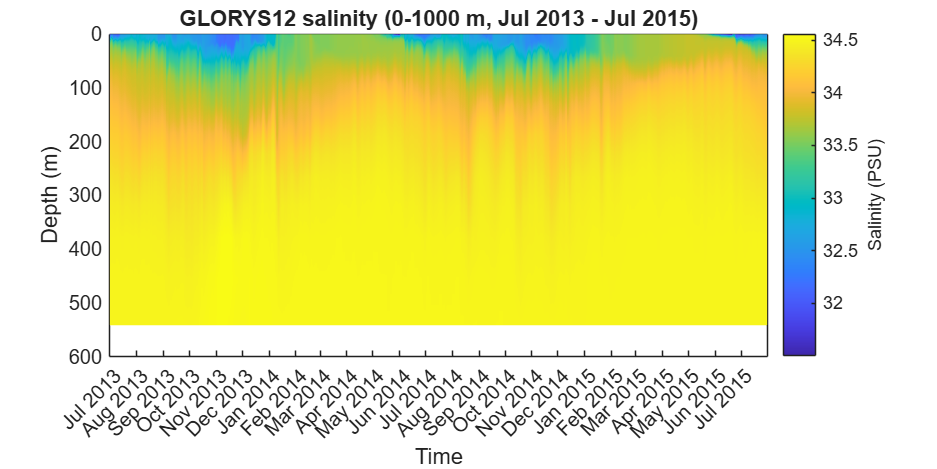


%% --- 6. Plot salinity ---
figure('Color','w','Position',[100 100 900 450]);
pcolor(tDateSub, zSub, Salsub); shading interp;
set(gca,'YDir','reverse');
ylim(depthLims);
try
    colormap(gca, cmocean('haline')); % requires cmocean toolbox
catch
    colormap(gca, 'parula');
end
cb = colorbar; ylabel(cb, 'Salinity (PSU)');
xlabel('Time'); ylabel('Depth (m)');
title('GLORYS12 salinity (0-1000 m, Jul 2013 - Jul 2015)');
ax = gca;
ax.XAxis.TickLabelFormat = 'MMM yyyy';
ax.XTick = dateshift(min(tDateSub),'start','month'):calmonths(1):dateshift(max(tDateSub),'start','month');


%% --- 7. TS diagram for a single profile (31 July 2014) ---
% Uses plot_ts_diagram.m (in the same folder) to convert practical
% salinity/potential temperature to Absolute Salinity / Conservative
% Temperature (TEOS-10) and plot with sigma0 density contours.
% Requires the GSW toolbox: http://www.teos-10.org/software.htm

targetDate = datetime(2015,7,19);
[~, idx] = min(abs(tDateSub - targetDate)); % nearest available time

fprintf('\nRequested date: %s\n', targetDate);


Requested date: 19-Jul-2015


fprintf('Nearest available date in subset: %s\n', tDateSub(idx));

Nearest available date in subset: 19-Jul-2015


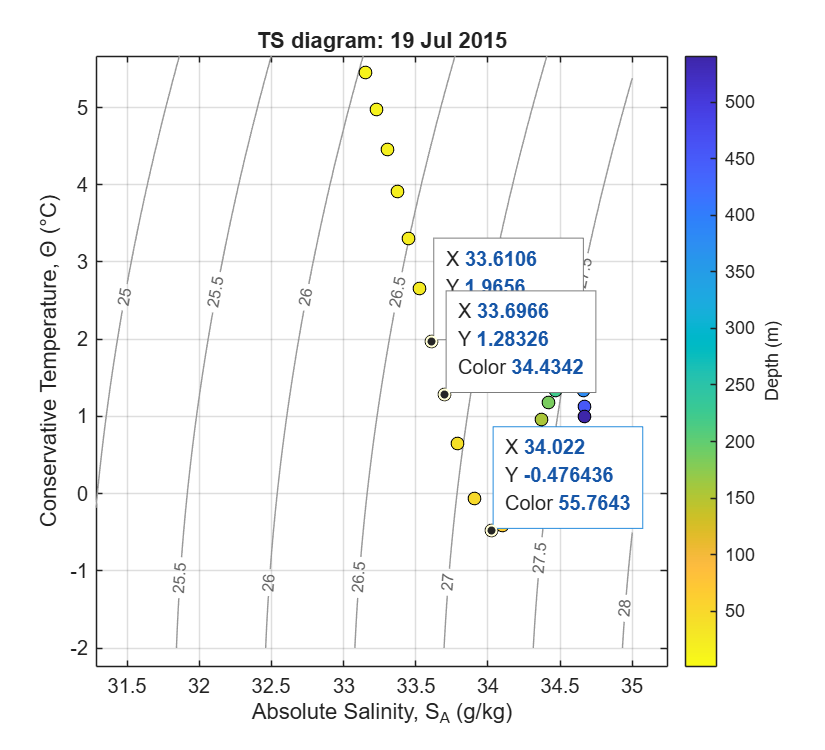


Tprofile   = Tsub(:, idx);   % potential temperature (thetao), degC
Salprofile = Salsub(:, idx); % practical salinity (so), PSU

% lon/lat of the extraction point (single-point file, so take the first/only value)
lonPt = lon(1);
latPt = lat(1);

[SA, CT, tsAx] = plot_ts_diagram(Salprofile, Tprofile, zSub, lonPt, latPt, ...
    'Title', sprintf('TS diagram: %s', datestr(tDateSub(idx), 'dd mmm yyyy')));


% Example of adding a water-mass label later, e.g.:
% hold(tsAx, 'on');
% plot(tsAx, 34.9, 2.0, 'kp', 'MarkerFaceColor','y', 'MarkerSize', 14);
% text(tsAx, 34.92, 2.0, 'AW', 'FontWeight','bold');